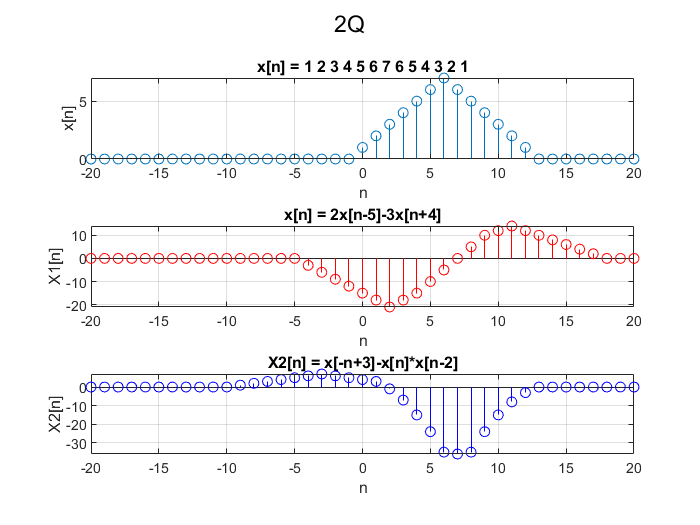

clc; % Clearing command window
close; % Closing all open figures
clearvars; % Clearing all variables

sgtitle("2Q")

syms y(x) % Creating a dynamic variable
y(x) = piecewise(x<0, 0,x==0, 1, x==1, 2,x==2, 3, x==3, 4,x==4, 5, x==5, 6,x==6, 7, x==7, 6,x==8, 5, x==9, 4,x==10, 3, x==11, 2,x==12, 1,x>12, 0); % Piecewise definition of x[n]
t=-20:1:20; % Initialising time range & time step
f=y(t); % Assigning f=y(t)
subplot(3,1,1) % Allotting plot tile 1 of 3x1 tiles
stem(t,f) % Discrete Time Plot of x[n]
title("x[n] = {1 2 3 4 5 6 7 6 5 4 3 2 1}") % Giving Plot Title
xlabel("n") % Assigning X-Label
ylabel("x[n]") % Assigning Y-Label
grid on % Enabling Grids

f1=2*y(t-5); % Assigning f1=2x[n-5]
f2=3*y(t+4); % Assigning f1=3x[n+4]
subplot(3,1,2) % Allotting plot tile 2 of 3x1 tiles
stem(t,f1-f2,"r") % Discrete Time Plot of X1[n]
title("x[n] = 2x[n-5]-3x[n+4]") % Giving Plot Title
xlabel("n") % Assigning X-Label
ylabel("X1[n]") % Assigning Y-Label
grid on % Enabling Grids

f3=y(-t+3); % Assigning f3=x[-n+3]
f4=y(t).*y(t-2); % Assigning f4=x[n]x[n-2]
subplot(3,1,3) % Allotting plot tile 3 of 3x1 tiles
stem(t,f3-f4,"b") % Discrete Time Plot o X2[n]
title("X2[n] = x[-n+3]-x[n]*x[n-2]") % Giving Plot Title
xlabel("n") % Assigning X-Label
ylabel("X2[n]") % Assigning Y-Label
grid on % Enabling Grids